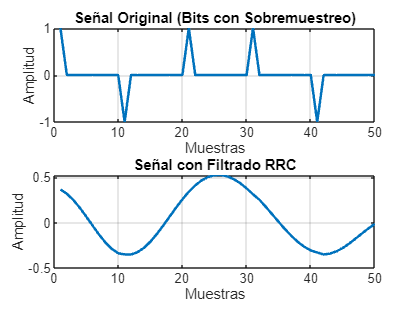

% Parámetros del filtro
rolloff = 0.25; % Factor de roll-off (0 a 1)
span = 6;       % Número de símbolos que abarca el filtro
samplesPerBit = 10; % Muestras por bit

% Crear el filtro RRC
rcFilter = rcosdesign(rolloff, span, samplesPerBit, 'sqrt');

% Generar el flujo de bits
bits = [1 0 1 1 0]; % Ejemplo
bitStream = upsample(2*bits-1, samplesPerBit); % Convertir bits a -1 y 1, y sobremuestrear

% Aplicar el filtro para formar los pulsos
shapedSignal = conv(bitStream, rcFilter, 'same');

% Graficar resultados
figure;
subplot(2,1,1);
plot(bitStream, 'LineWidth', 1.5);
title('Señal Original (Bits con Sobremuestreo)');
xlabel('Muestras');
ylabel('Amplitud');
grid on;

subplot(2,1,2);
plot(shapedSignal, 'LineWidth', 1.5);
title('Señal con Filtrado RRC');
xlabel('Muestras');
ylabel('Amplitud');
grid on;